# 绘制分形树叶图

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

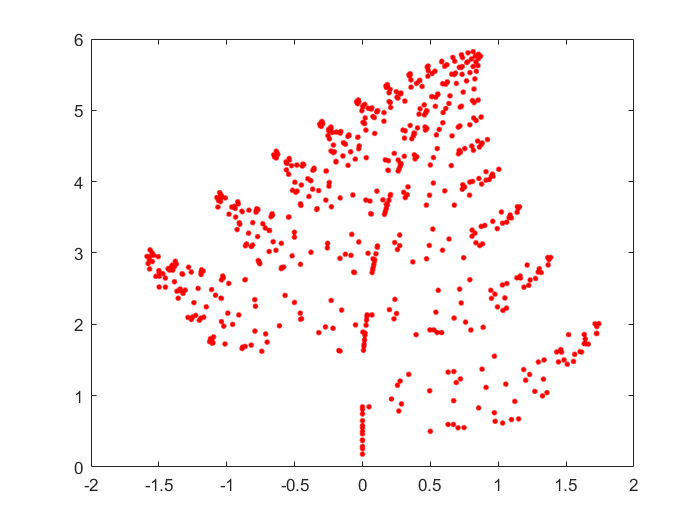

clear;clc;
% 初始点的位置
x = [0.5; 0.5];        
% 绘制初始点
plot(x(1), x(2), '.r', 'MarkerSize', 10); 
% 设置判断向量
h = [0.75, 0.90, 0.98, 1.00];
b1 = [0; 1.5];
b2 = [0; 1.5];
b3 = [0; 0.4];
% 构造仿射变换矩阵
A1 = [0.75, 0.04; -0.04, 0.75];
A2 = [0.20, -0.3; 0.25, 0.23];
A3 = [-0.15, 0.32; 0.26, 0.24];
A4 = [0, 0; 0, 0.15];
%循环绘制
hold on

for i = 1 : 1000
    r = rand;
    if r < h(1)
        x = A1 * x + b1;
    elseif r < h(2)
        x = A2 * x + b2;
    elseif r < h(3)
        x = A3 * x + b3;
    else
        x = A4 * x;
    end
    plot(x(1), x(2), '.r', 'MarkerSize', 10);
    pause(0.001);
    % drawnow 太慢了
end
hold off